data=ProcessedDataset25x30720;
testData=ProcessedTest3Dataset25x30720;


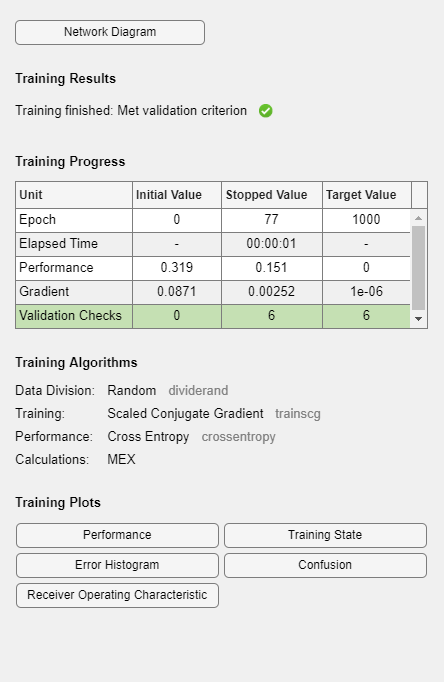

var=8;
range=2;
[G,ID] = findgroups(data(:,end));
target = ind2vec((G).');
x = data(:,var:end-1).';
testPerf=[];
testAcc=[];
for j=1:2
        perf=[];
        acc=[];
        for i=1:range
        net = patternnet(i);
        net.performFcn = 'crossentropy';
        [net,tr] = train(net,x,target);
        y = net(data(tr.testInd,var:end-1).');
        [G,ID] = findgroups(data(tr.testInd,end));
        testTarget = ind2vec((G).');
        perf(i) = perform(net,testTarget,y);
        [c,cm] = confusion(testTarget,y);
        acc(i)=100*(1-c);
        
        xt=testData(:,var:end-1).';
        yt=net(xt);
        [G,ID] = findgroups([data(:,end);testData(:,end)]);
        TrueTarget = ind2vec((G(1401:end,1)).');
        Tperf(i) = perform(net,TrueTarget,yt);
        [c,cm] = confusion(TrueTarget,yt);
        Tacc(i)=100*(1-c);
    end
        testPerf= vertcat(testPerf,perf);
        testAcc= vertcat(testAcc,Tacc);
testDataPerf=[perf;acc;Tperf;Tacc];
end


meanTestPerf=[];
meanAccPerf=[];
for k=1:range
meanTestPerf(k)= mean(testPerf(:,k));
meanAccPerf(k)= mean(testAcc(:,k));
end


min(meanTestPerf)

ans = 0.1390

find(meanTestPerf==min(meanTestPerf))

ans = 2


max(meanAccPerf)

ans = 39.5000

find(meanAccPerf==max(meanAccPerf))

ans = 1

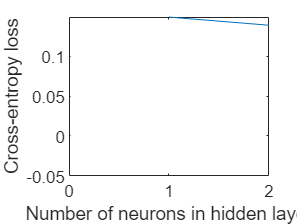

figure(1)
plot(1:i,meanTestPerf(1:i));
axis([0 i -0.05 inf])
xlabel('Number of neurons in hidden layer')
ylabel('Cross-entropy loss')

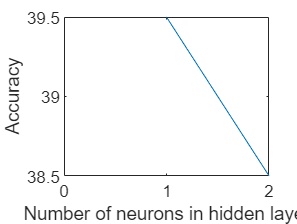

figure(2)
plot(1:i,meanAccPerf(1:i));
    axis([0 i -inf inf])
xlabel('Number of neurons in hidden layer')
ylabel('Accuracy')

% figure(3)
% plot(1:i,testDataPerf(3,:));
% axis([0 50 -0.05 inf])

% figure(3)
% plot(1:i,testDataPerf(4,:));
% axis([0 50 -inf 110])

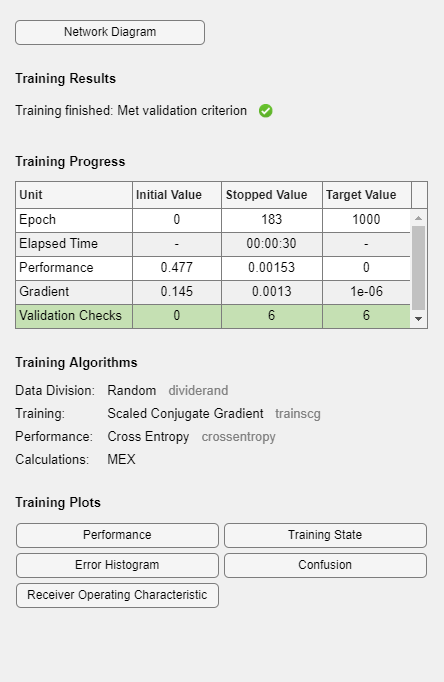


net = patternnet(19);
net.performFcn = 'crossentropy';
[net,tr] = train(net,x,target);

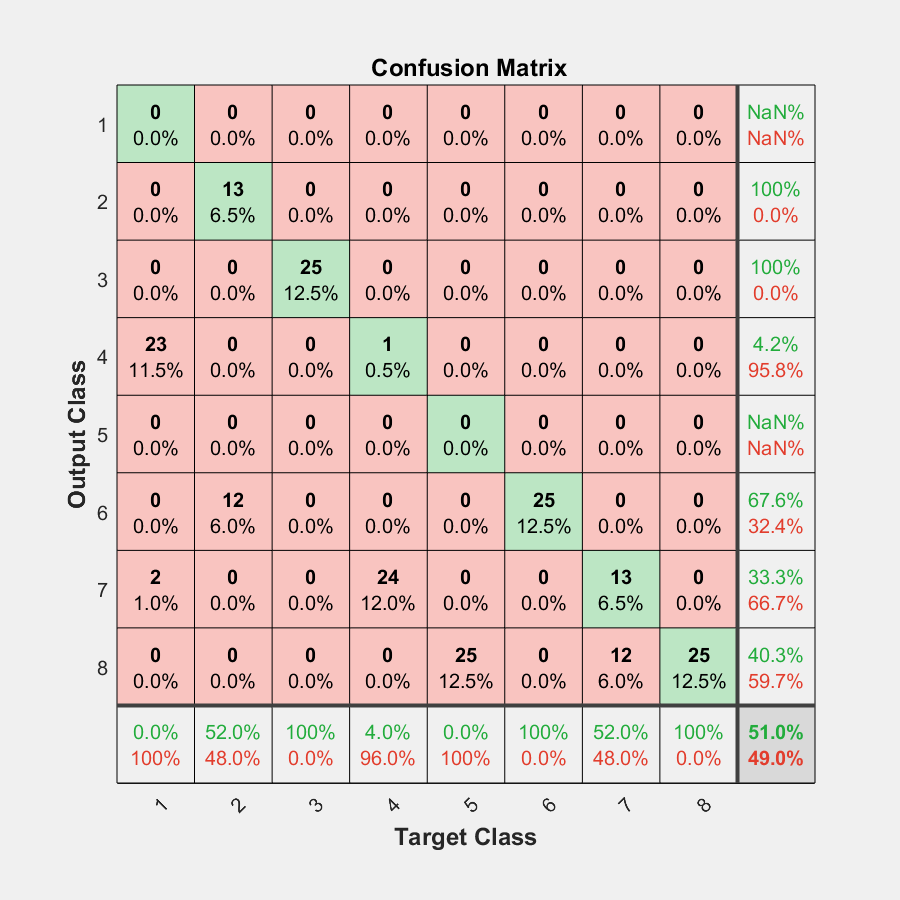



testX = testData(:,var:end-1).';
[G,ID] = findgroups([data(:,end);testData(:,end)]);
testT = ind2vec((G(1401:end,1)).');

testY = net(testX);
figure(3)
plotconfusion(testT,testY);